**Experiment - 4                                                                             Date - 15/2/2024**

**Aim :- Estimate signal spectra using Discrete Fourier Transform(DFT) and Fast Fourier Transfor(FFT) .**

**Laboratory Exercises**

A) Write a MATLAB Program to compute and plot the L-point DFT X[k] of a sequence x[n] of length N with L>= N and then to compute and plot as dftuser() and idftuser() for DFT ad IDFT , respectively .

clc ; clear all ; close all ;

xn = [1 2 3 4 5 6] ; L = 8 ; [X , k]= dftuser(xn,L) ;
disp(X) ;

  21.0000 + 0.0000i  -9.6569 - 3.0000i   3.0000 - 4.0000i   1.6569 + 3.0000i  -3.0000 - 0.0000i   1.6569 - 3.0000i   3.0000 + 4.0000i  -9.6569 + 3.0000i




clc ; clear all ; close all ;
X = [   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -9.6569 + 3.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i] ;
N = 8 ; [xn, n] = idftuser(X , N) ;
disp(xn) ;

  -1.2071 + 0.3750i  -0.5884 + 1.1187i   0.3750 + 1.2071i   1.1187 + 0.5884i   1.2071 - 0.3750i   0.5884 - 1.1187i  -0.3750 - 1.2071i  -1.1187 - 0.5884i



% function [X , k] = dftuser(xn,L)
%     N = length(xn) ;
%     X = [zeros(1,L)] ;
%     for k = 1:L
%         for n = 1:N 
%             X(k) = X(k) + xn(n) * exp(-1i * (2*pi/L) * (k-1) * (n-1));
%         end
%     end  
%     k = 0 : L-1 ;
% end

% function [xn, n] = idftuser(X , N)
%     L = length(X) ; 
%     xn = [zeros(1,N)] ;
%     for k = 1:N
%         for n = 1:L 
%             xn(n) = xn(n) + X(k) * exp(1i * (2*pi/L) * (k-1) * (n-1)) ;
%         end
%     end  
%    xn = xn/L ; n = 0 : N-1 ;
% end

**Inference : -  The above functions computes DFT and IDFT for any given sequence . These functions help us to analyse Frequency Component of the input sequence .**

B) This exercise is aimed to identify how fast fft() is compared to regular DFT . For that reason , create a sinusoid that has the three spectral components of 50 , 100 and 250 Hz , and sample this signal at 1000Hz . The duration of the signal so that you end up with 1024 points . You will test various implementations of DFT(dftuser() vs. fft() ) on this three frequency test signal . Use tic and toc for timing comparison .

clc ; clear all ; close all ;
%Declaring Original Signal
freq1 = 50 ; samp1 = 1000 ; dur = 1.023 ;

t1 = 0 : (1/samp1) : dur ; x1 = sin(2*pi*freq1*t1) ;

freq2 = 100 ; x2 = sin(2*pi*freq2*t1) ;
freq3 = 250 ; x3 = sin(2*pi*freq3*t1) ;

x = x1 + x2 + x3 ; L = 1024 ; 
tic ; X = dftuser(x , L) ; A = idftuser(x , L) ; toc ;

Elapsed time is 0.574104 seconds.


tic ; Z = fft(x , L) ; toc ;

Elapsed time is 0.000206 seconds.


**Inference : - Clearly , FFT has better computing speed than DFT and due to this it is widely used in Digital Signal Processing . Here , time increases with increase in the value of N .**

C) A continuous time signal x(t) = sin(20pit) is sampled at 64Hz to obtain x[n] . If we denote X[k] as a 32 point DFT of x[n] , then identify the peak amplitude and their respective indices k in MATLAB . Repeat the problem for a signal with analog frequency of 11 Hz . You need to use dftuser() as implemented in the previous exercise .

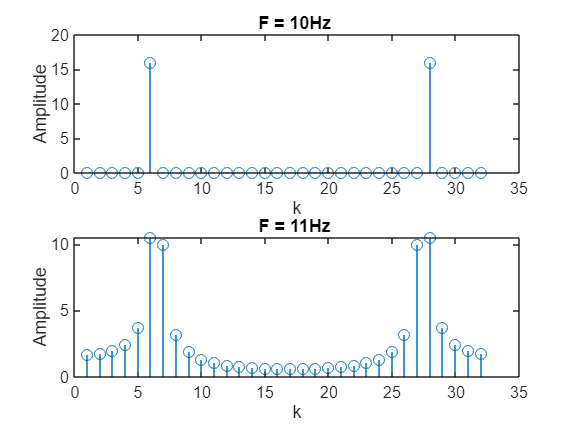

clc ; clear all ; close all ;

fs = 64 ; L = 32 ; t = 0 : 1/fs : (L-1)/fs ;
x15 = sin(20*pi*t) ;
[X1] = dftuser(x15 , L) ;

x23 = sin(22*pi*t) ;
[X2] = dftuser(x23 , L) ;

subplot(2,1,1) ; stem(abs(X1)) ; xlabel("k") ; ylabel("Amplitude") ; title('F = 10Hz ') ;
subplot(2,1,2) ; stem(abs(X2)) ; xlabel("k") ; ylabel("Amplitude") ; title('F = 11Hz ') ;

**Inference :- The peak amplitude when Frequency = 10 Hz is obtained two symmetric points whereas the peak amplitude when Frequency = 11 Hz is to be obtained at two symmetric points along with the nearby points having some amplitude .**

**From the peak amplitude we can find the major frequency component and its corresponding index in the Frequency Domain .**

D)This exercise illustrates methods to compute linear convolution along with its timing requirements . Create a sinusoid with the three spectral components of 50 , 100 and 200 Hz , and sample this signal at 1000 Hz . Determine the duration of the signal so that you end up with 1024 points . The LTI system is described with the difference equation same as Experiment 3 , eq(1) . Determine the convoluted output using three methods , direct linear convolution , using circular convolution and via DFT and IDFT , and compare timing requirements . 

clc ; clear all ; close all ;
%Declaring Original Signal
freq1 = 50 ; freq2 = 100 ; freq3 = 200 ;  samp1 = 1000 ; dur = 1.023 ;

t1 = 0 : (1/samp1) : dur ;
x1 = sin(2*pi*freq1*t1) + sin(2*pi*freq2*t1) + sin(2*pi*freq3*t1) ; n = length(x1) ;

%plot(t1,x1) ; xlabel("Time") ; ylabel("Amplitude") ; title("Original Signal") ; grid on ;

h1n = [0.25 0.5 0.25] ; m = length(h1n) ; 
x2 = [x1,zeros(1,m-1)] ; h2n = [h1n,zeros(1,n-1)] ;

tic 
yn = conv(x1,h1n) ;
toc

Elapsed time is 0.961888 seconds.


tic
ync = cconv(x2,h2n) ; 
toc

Elapsed time is 1.693031 seconds.


tic
xnl = fft(x2,n+m-1) ; hnl = fft(h2n,n+m-1) ; ynl = xnl .*hnl ; ynd = ifft(ynl,n+m-1); 
toc

Elapsed time is 0.024024 seconds.


**Inference :- The above code is a comparison between different methods to find linear convolution . From this we determine that Convolution via DFT/IDFT Method take the least time to compute the Linear Convolution and overall requires less amount of Hardware (ADD and MUL).**

**Conclusion :-  In this experiment , we learnt to compute DFT and IDFT using UDF and also applied the FFT function to compare the timing requirements . We further compared the different methods to find Linear Convolution and measured their computational time . This experiment help us to learn about the importance of DFT / IDFT has in real life applications and hardware used for Digital Signal Processing .**